clc; clear;

E_in = 10.06

E_in = 10.0600

E = [6.30 8.64]

E =     6.3000    8.6400


t = [25.85 53.98]

t =    25.8500   53.9800


C = 535.153e-6

C = 5.3515e-04

R = 50.3e3

R = 50300


t_theory = linspace(0, 3*R*C)

t_theory =          0    0.8157    1.6314    2.4471    3.2628    4.0785    4.8942    5.7099    6.5256    7.3413    8.1570    8.9727    9.7884   10.6041   11.4198   12.2355   13.0512   13.8669   14.6827   15.4984   16.3141   17.1298   17.9455   18.7612   19.5769   20.3926   21.2083   22.0240   22.8397   23.6554   24.4711   25.2868   26.1025   26.9182   27.7339   28.5496   29.3653   30.1810   30.9967   31.8124   32.6281   33.4438   34.2595   35.0752   35.8909   36.7066   37.5223   38.3380   39.1537   39.9694


curve = E_in*(1-exp(-t_theory/(R*C)))

curve =          0    0.3003    0.5916    0.8742    1.1484    1.4144    1.6724    1.9228    2.1657    2.4013    2.6299    2.8517    3.0669    3.2756    3.4781    3.6746    3.8651    4.0501    4.2294    4.4035    4.5723    4.7361    4.8950    5.0492    5.1988    5.3439    5.4846    5.6212    5.7537    5.8822    6.0069    6.1279    6.2453    6.3591    6.4696    6.5768    6.6807    6.7816    6.8795    6.9744    7.0665    7.1558    7.2425    7.3266    7.4082    7.4874    7.5642    7.6387    7.7109    7.7810


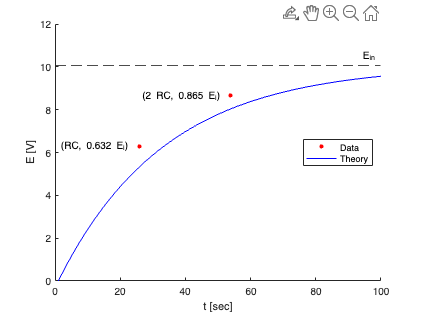


figure
hold on
xlabel("t [sec]")
ylabel("E [V]")
plot(t, E, "Marker",".", "LineStyle","none", "Color", "Red", "MarkerSize", 12)
text(t(1), E(1), '(RC, 0.632 E_i)  ', HorizontalAlignment="right")
text(t(2), E(2), '(2 RC, 0.865 E_i)  ', HorizontalAlignment="right")
plot(curve, "Color", "Blue", "LineWidth", 1)    
yline(E_in, "Color", "Black", "LineWidth", 1, "LineStyle","--", Label="E_{in}")
legend("Data", "Theory", Location="East")
hold off

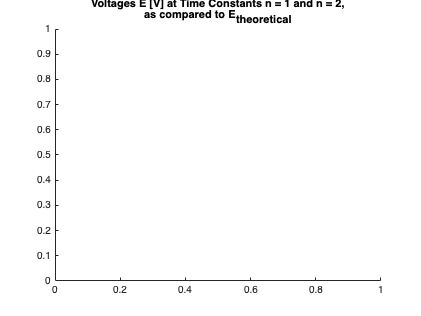


figure
title(["Voltages E [V] at Time Constants n = 1 and n = 2,", "as compared to E_{theoretical}"])